# Aprende Cálculo en el Editor en Vivo

#### **Aprende cálculo y matemáticas aplicadas usando Symbolic Math Toolbox™. **

El ejemplo muestra las funciones introductorias fplot y diff. Para manipular una variable simbólica, crea un objeto de tipo syms.

syms x

Una vez que una variable simbólica está definida, puedes construir y visualizar funciones con fplot.

f(x) = 1/(5+4*cos(x))

$$f(x) = \frac{1}{4\,\cos\left(x\right)+5}$$

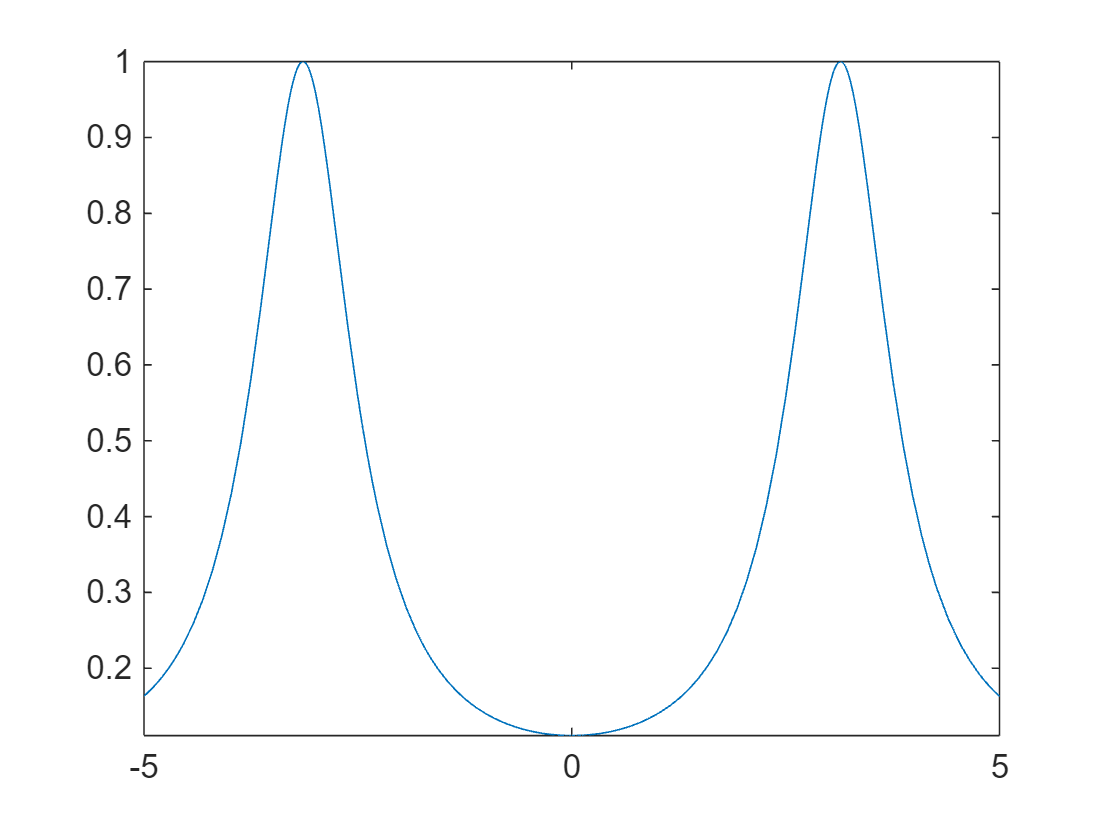

fplot(f)

Evalúa la función usando notación matemática.

f(pi/2)

$$ans = \frac{1}{5}$$

%f("pi/2")

Muchas funciones pueden trabajar con variables simbólicas. Por ejemplo, diff diferencia una función.

f1 = diff(f) 

$$f1(x) = \frac{4\,\sin\left(x\right)}{{\left(4\,\cos\left(x\right)+5\right)}^{2}}$$

fplot(f1) 

diff también puede encontrar la derivada n-ésima. Aquí está la segunda derivada.

f2 = diff(f,2) 

$$f2(x) = \frac{4\,\cos\left(x\right)}{{\left(4\,\cos\left(x\right)+5\right)}^{2}}+\frac{32\,{\sin\left(x\right)}^{2}}{{\left(4\,\cos\left(x\right)+5\right)}^{3}}$$

fplot(f2) 

`int` integra funciones de variables simbólicas. A continuación se intenta recuperar la función original integrando la segunda derivada dos veces.

g = int(int(f2)) 

$$g(x) = -\frac{8}{{\tan\left(\frac{x}{2}\right)}^{2}+9}$$

fplot(g)

A primera vista, las gráficas de f y g parecen iguales. Sin embargo, observa cuidadosamente sus fórmulas y sus rangos en el eje `y`.

subplot(1,2,1) 
fplot(f) 
subplot(1,2,2) 
fplot(g)

$e$ es la diferencia entre f y g. Tiene una fórmula complicada, pero su gráfica parece una constante.

e = f - g 

$$e(x) = \frac{8}{{\tan\left(\frac{x}{2}\right)}^{2}+9}+\frac{1}{4\,\cos\left(x\right)+5}$$

Para mostrar que la diferencia realmente es una constante, simplifica la ecuación. Esto confirma que la diferencia entre ellas realmente es una constante.

e = simplify(e) 

$$e(x) = 1$$